## Select TCSPC data and show data dimensions of dataseries in file

%% select TCSPC data and show data dimensions of dataseries in file
% add path to bioformats
addpath('bfmatlab');

javaaddpath('bfmatlab\bioformats_package.jar');


% select file
[file,path] = uigetfile('*.*','select TCSPC file');

% get get dimensions of dataseries in file
[warnings,XYZTC] = evalc('bf_file_info(strcat(path,file))');

Unrecognized function or variable 'bfGetReader'.

Error in bf_file_info (line 4)
reader = bfGetReader(filepath);
^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

% display dimensions of dateseries
disp(XYZTC);

## Load Data

dataseries = 1;
[warnings, raw_data] = evalc('bf_load_parts_v7(strcat(path,file),dataseries,-1,-1,-1,-1,-1)'); % use evalc to block annoying bioformats warnings
data = squeeze(raw_data);
disp('Done')

Done


## Display TCSPC trace

Sums up the TCSPC signal of all pixels and displays TCSPC trace in a semilogarithmic plot. Use this to time positions of laser pulses to set up the start parameters for the irf fit (x0_irf).

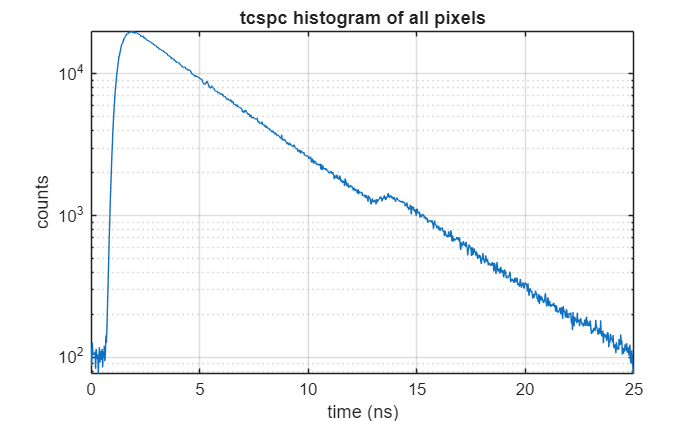

% generate time axis t
t = (0:size(data,3)-1)*dt;
% sum up all the pixels in the image
tcspc_trace = squeeze(sum(data,[1,2]));
% plot in semilogarithmic plot
semilogy(t,tcspc_trace);
grid on; xlabel('time (ns)'); ylabel('counts'); title('tcspc histogram of all pixels')

## Generate mask

All pixels in mask get summed up.

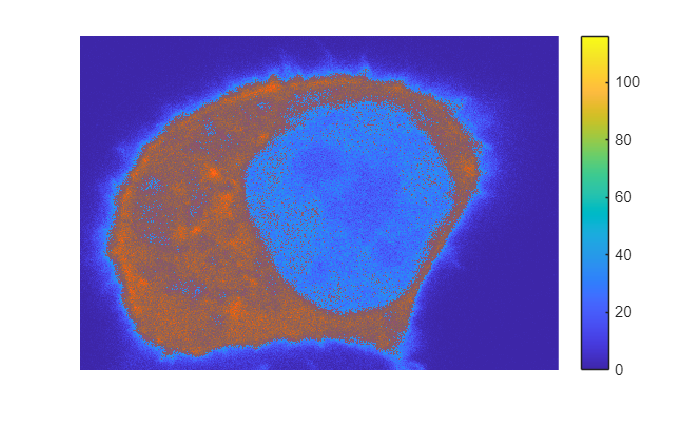

% sum up all time bins to generate normal 2D image
data_t_sum = squeeze(sum(data,3));

% set mask threshold
mask_threshold = 40;
mask = data_t_sum>mask_threshold;

% generate mask using Otsu's threshold
% [counts,x] = imhist(data_t_sum,max(data_t_sum,[],'all'));
% T = otsuthresh(counts);
% mask = imbinarize(data_t_sum,T);

% make mask
imagesc(data_t_sum);
colormap('parula');
colorbar;
hold on;
red_mask = cat(3, ones(size(mask)), zeros(size(mask)), zeros(size(mask)));
h_mask = imshow(red_mask);
opacity = 0.5;
set(h_mask, 'AlphaData', mask * opacity);
hold off;

## Sum up all pixels in mask

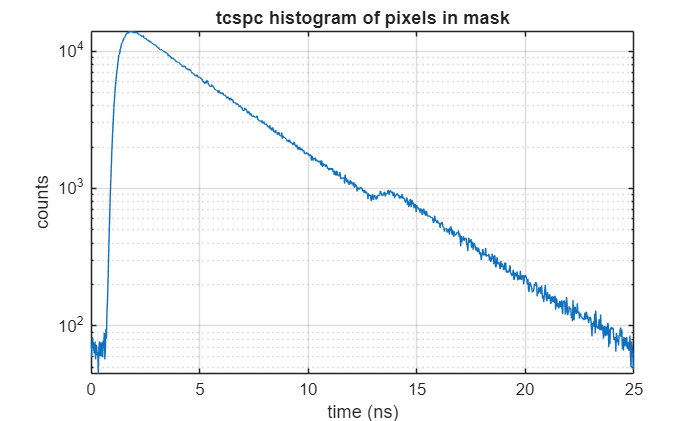

n_t_bins = size(data,3);
data_xy_sum = zeros(1,1,n_t_bins);
for i = 1 : n_t_bins
    dmy = data(:,:,i);
    data_xy_sum(1,1,i) = sum(dmy(mask),'all');
end

% plot in semilogarithmic plot
semilogy(t,squeeze(data_xy_sum));
grid on; xlabel('time (ns)'); ylabel('counts'); title('tcspc histogram of pixels in mask')

## Fit IRF and data with biexponential fit

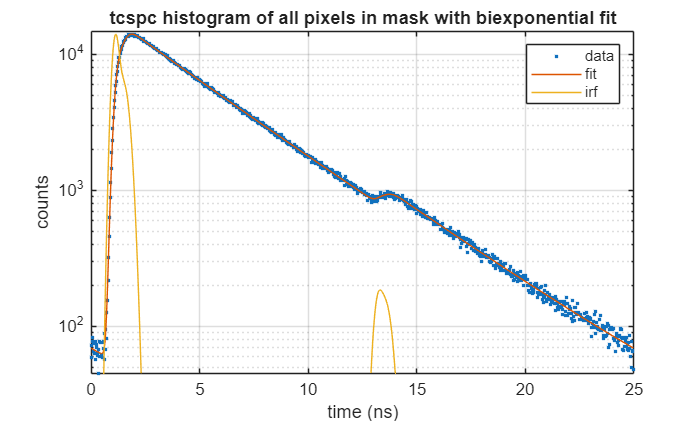

x0 = [1,4]; lb = [0.1, 2]; ub = [5, 10];
x0_irf = [1.2, 0.15, 1.2, 0.3, 0.05, 13.5, 0.2, 0.02, 13.5, 0.3, 0.02];
lb_irf = [0.5, 0.1, 0.5, 0.1, 0.005, 12.8, 0.2, 0.002, 12.7, 0.2, 0.002];
ub_irf = [1.9, 1.5, 1.9, 3.0, 0.500, 14.2, 2.0, 0.20, 14.2, 3.0, 0.20];
cost_type = 'MLE';
fit_bg = true;
error_type = '95CI';

[r_fitirf, r_fitirf_fit, irf_fit] = fit_tcspc_gauss_irf_varpro(t, data_xy_sum, x0, lb, ub, x0_irf, lb_irf, ub_irf, cost_type, fit_bg, error_type);
% [warning,r_fitirf, r_fitirf_fit, irf_fit] = evalc('fit_tcspc_gauss_irf_varpro(t, data_xy_sum, x0, lb, ub, x0_irf, lb_irf, ub_irf, cost_type, fit_bg_fitirf, error_type)');


semilogy(t,squeeze(data_xy_sum),'.','DisplayName','data');
hold on;
semilogy(t,r_fitirf_fit,'DisplayName','fit');
semilogy(t,irf_fit./max(irf_fit)*max(r_fitirf_fit),'DisplayName','irf');
hold off
grid on;
legend;
xlabel('time (ns)'); ylabel('counts');title('tcspc histogram of all pixels in mask with biexponential fit');
ylim([min([min(r_fitirf_fit) min(data_xy_sum)]) max(r_fitirf_fit)*1.05]);

% print fit parameters
disp([char(964), '_1: ',num2str(r_fitirf.taus(1)),' ns ', char(177),' ', num2str(r_fitirf.err_vals.taus(1)),' ns', ...
    newline, char(964), '_2: ',num2str(r_fitirf.taus(2)),' ns', char(177),' ', num2str(r_fitirf.err_vals.taus(2)),' ns', ...
    newline, 'background: ',num2str(r_fitirf.background), char(177),' ', num2str(r_fitirf.err_vals.background)]);

τ_1: 3.1517 ns ± 1.0792 ns
τ_2: 4.2926 ns± 0.84761 ns
background: 8.5063± 1.4802


## Fit IRF and data with monoexponential fit

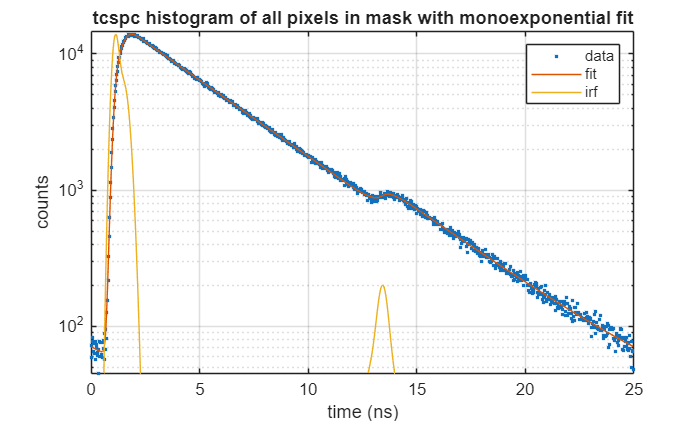

x0 = [1]; lb = [0.1]; ub = [10];
x0_irf = [1.2, 0.15, 1.2, 0.3, 0.05, 13.5, 0.2, 0.02, 13.5, 0.3, 0.02];
lb_irf = [0.5, 0.1, 0.5, 0.1, 0.005, 12.8, 0.2, 0.002, 12.7, 0.2, 0.002];
ub_irf = [1.9, 1.5, 1.9, 3.0, 0.500, 14.2, 2.0, 0.20, 14.2, 3.0, 0.20];
cost_type = 'MLE';
fit_bg = true;
error_type = '95CI';

[r_fitirf, r_fitirf_fit, irf_fit] = fit_tcspc_gauss_irf_varpro(t, data_xy_sum, x0, lb, ub, x0_irf, lb_irf, ub_irf, cost_type, fit_bg, error_type);
% [warning,r_fitirf, r_fitirf_fit, irf_fit] = evalc('fit_tcspc_gauss_irf_varpro(t, data_xy_sum, x0, lb, ub, x0_irf, lb_irf, ub_irf, cost_type, fit_bg_fitirf, error_type)');


semilogy(t,squeeze(data_xy_sum),'.','DisplayName','data');
hold on;
semilogy(t,r_fitirf_fit,'DisplayName','fit');
semilogy(t,irf_fit./max(irf_fit)*max(r_fitirf_fit),'DisplayName','irf');
hold off
grid on;
legend;
xlabel('time (ns)'); ylabel('counts');title('tcspc histogram of all pixels in mask with monoexponential fit');
ylim([min([min(r_fitirf_fit) min(data_xy_sum)]) max(r_fitirf_fit)*1.05]);

disp([char(964), '_1: ',num2str(r_fitirf.taus(1)),' ns ', char(177),' ', num2str(r_fitirf.err_vals.taus(1)),' ns', ...
    newline, 'background: ',num2str(r_fitirf.background), char(177),' ', num2str(r_fitirf.err_vals.background)]);

τ_1: 3.8573 ns ± 0.0090387 ns
background: 17.5728± 1.2022
